clc;
clear;
close all;

addpath('C:\Users\soumy\Desktop\matlab_function\TA');

 addpath('C:\Users\soumy\Desktop\matlab_function\TA\colourschemes');


dataIOAssembly = NET.addAssembly('C:\Users\soumy\Desktop\matlab_function\TA\Net Assembly\OpenScanFilesFull.dll');

range=750:1950; % For vis measurements (full range)

%------Define experiment directory paths -----------------%
scanDir ='C:\Users\soumy\Desktop\mitrasou\mitrasou\2020-10-13_FeQsal_LS_RT\spot3_newsamplecut\7ps_20fsstep_1uJ_2mJcm2_125Hz';

[timeDelays,wavelengths,dA,scanLen,lenTime]=readData(scanDir,range);

scanNum = 1

scanNum = 2

scanNum = 3

scanNum = 4

scanNum = 5

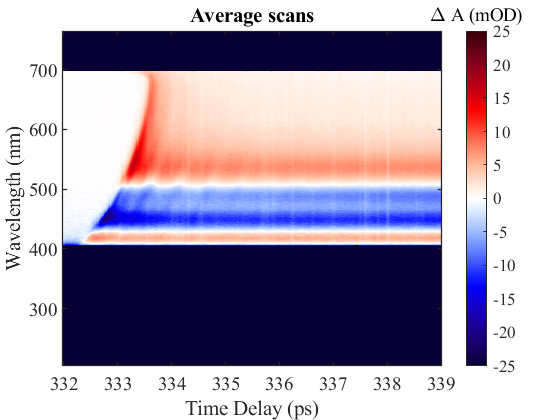

dA(:,:,:)=cleanDATA(scanLen,lenTime,dA(:,:,:),range);

sig=3;

filtA(:,:)=med_filt(scanLen,lenTime,dA(:,:,:),sig,range);

CT=cptcmap('dkbluered');
Min=-25;
Max=25;
lambda=wavelengths;

figure();imagesc(timeDelays./1000,wavelengths, filtA',[Min Max]);set(gcf,'color','w');set(gca,'fontname','times');set(gca,'FontSize',14,'linewidth',1);set(gca,'YDir','normal')
xlabel('Time Delay (ps)');ylabel('Wavelength (nm)'); 
colormap(CT);
hcb=colorbar; title(hcb,'\Delta A (mOD)','fontsize',14,'fontname','times');set(hcb,'fontsize',13,'fontname','times','ylim', [Min Max]);title(['Average scans']);

## Setting the range for analysis and finding tzero

range1=780:1800;
poly_order=7;
TimevectorLength=length(timeDelays);
counter=1;
tzero=TZero(filtA,range1,timeDelays,TimevectorLength,counter);

## Chirp correction 

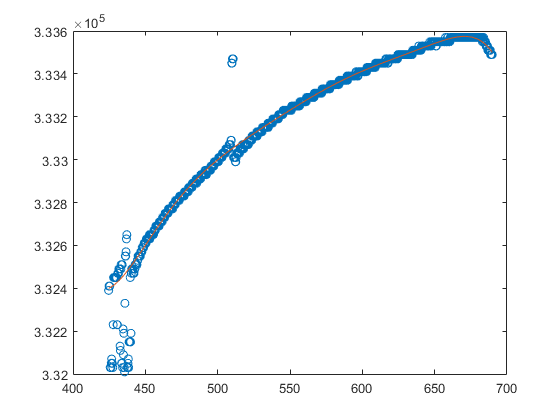

shift=TimeShift(lambda,tzero,poly_order,range1);

## Interpolation on filtA (Chirp Correction)

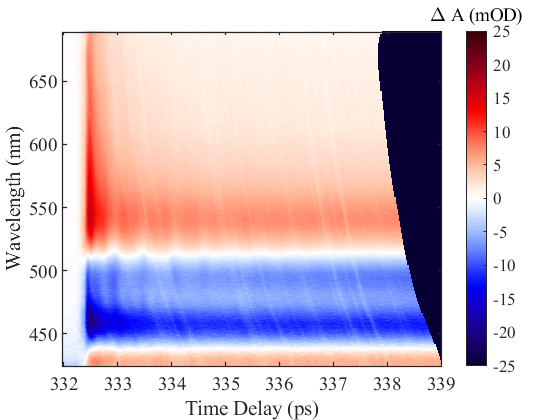

filtA_corr=Chirp_Correction(filtA,shift,range1,timeDelays);

figure();
imagesc(timeDelays./1000,lambda(range1),filtA_corr',[-25 25]);set(gcf,'color','w');set(gca,'fontname','times');set(gca,'FontSize',14,'linewidth',1);set(gca,'YDir','normal')

xlabel('Time Delay (ps)');ylabel('Wavelength (nm)');
colormap(CT);
hcb=colorbar; title(hcb,'\Delta A (mOD)','fontsize',14,'fontname','times');set(hcb,'fontsize',13,'fontname','times','ylim', [-25 25]);

## Reducing time axis because of chirp

sub=60; %Reducing Number of points in the time axis

del=TimevectorLength-sub;
counter1=2;
tzero1=TZero(filtA_corr,range1,timeDelays,del,counter1);

tzero_map=mode(tzero1);
time=(timeDelays-tzero_map)./1000;

## SVD

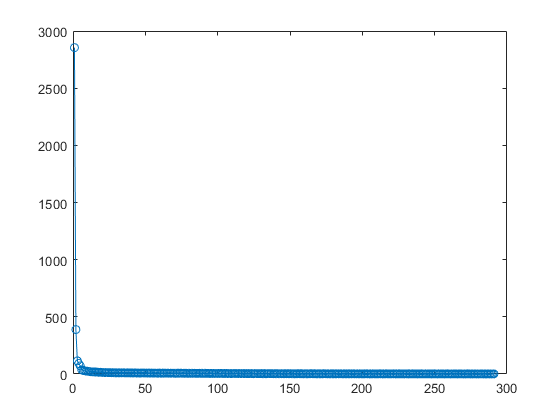

% SVD=1;
plot_components=0;
comp=6;

[data,res]=SVD(filtA_corr,wavelengths,time,range1,plot_components,del,comp);

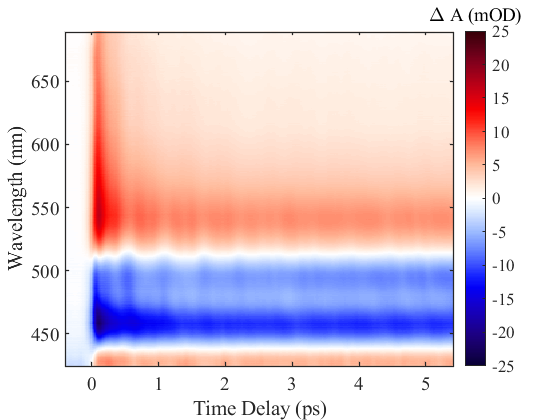

figure();
imagesc(time(1:del),wavelengths(range1),data',[-25 25]);set(gcf,'color','w');set(gca,'fontname','times');set(gca,'FontSize',14,'linewidth',1);set(gca,'YDir','normal')
xlabel('Time Delay (ps)');ylabel('Wavelength (nm)'); 
colormap(CT);
hcb=colorbar; title(hcb,'\Delta A (mOD)','fontsize',14,'fontname','times');set(hcb,'fontsize',13,'fontname','times','ylim', [-25 25]);

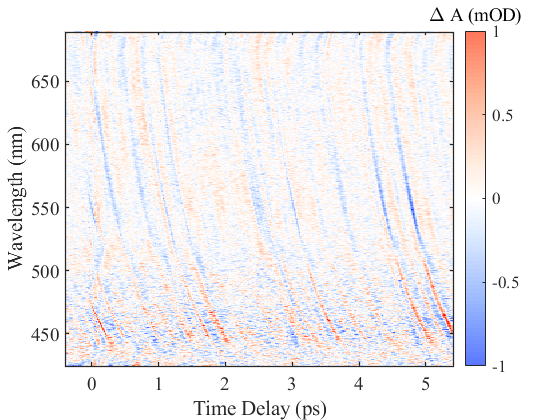


figure();
imagesc(time(1:del),wavelengths(range1),res',[-3 3]);set(gcf,'color','w');set(gca,'fontname','times');set(gca,'FontSize',14,'linewidth',1);set(gca,'YDir','normal')
xlabel('Time Delay (ps)');ylabel('Wavelength (nm)'); 
colormap(CT);
hcb=colorbar; title(hcb,'\Delta A (mOD)','fontsize',14,'fontname','times');set(hcb,'fontsize',13,'fontname','times','ylim', [-1 1]);

## SVD Filter

SVD_filter=1;

if SVD_filter == 1
filtA_corr=data;
end

## **Global Analysis**


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          6          138316                      5.75e+04
     1         12          133837             10       2.04e+04      
     2         18          132466             20       3.93e+03      
     3         24          132127             40            716      
     4         30          130893             80       1.37e+03      
     5         36          126798        74.0759        2.4e+03      
     6         42          122514        6.63723       3.43e+03      
     7         48          116351            160          4e+03      
     8         54          109585            320       5.42e+03      
     9         60          104631            640       5.73e+03      
    10         66          102371       0.090988       3.92e+03      
    11         72          101667      0.0554211       2.16e+03      
    12         78          10151


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          6          138316                      5.75e+04
     1         12          133837             10       2.04e+04      
     2         18          132466             20       3.93e+03      
     3         24          132127             40            716      
     4         30          130893             80       1.37e+03      
     5         36          126798        74.0759        2.4e+03      
     6         42          122514        6.63723       3.43e+03      
     7         48          116351            160          4e+03      
     8         54          109585            320       5.42e+03      
     9         60          104631            640       5.73e+03      
    10         66          102371       0.090988       3.92e+03      
    11         72          101667      0.0554211       2.16e+03      
    12         78          10151

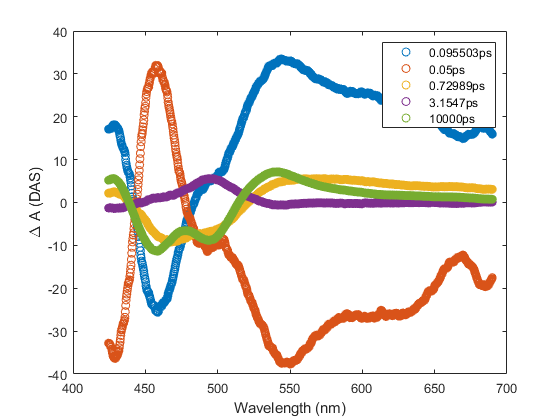

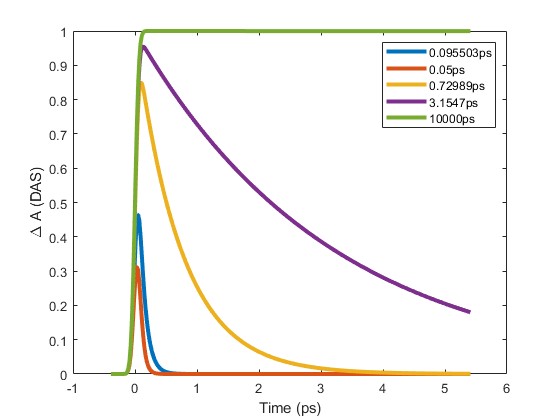

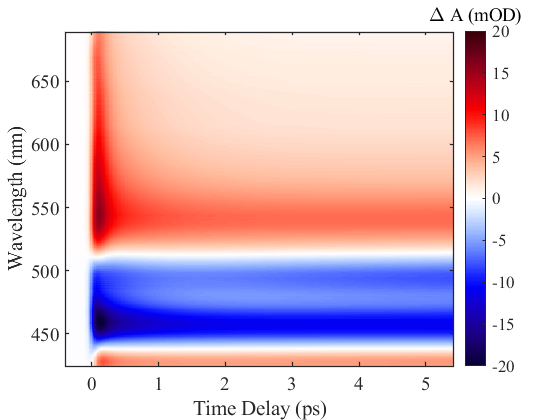

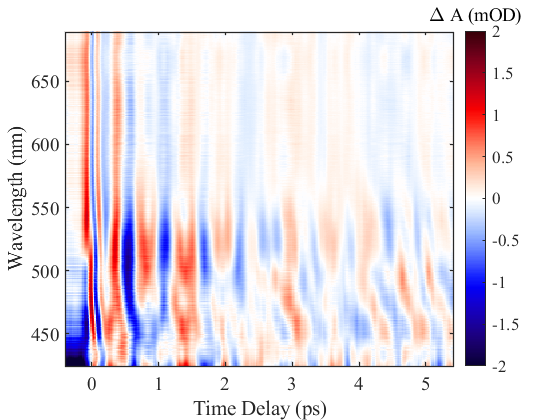

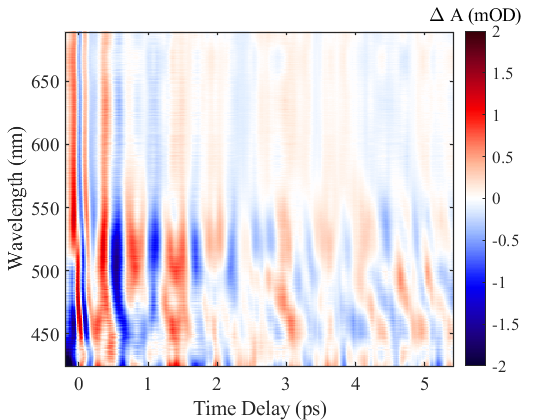

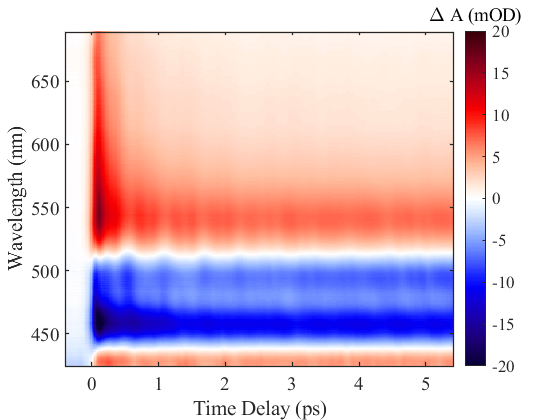

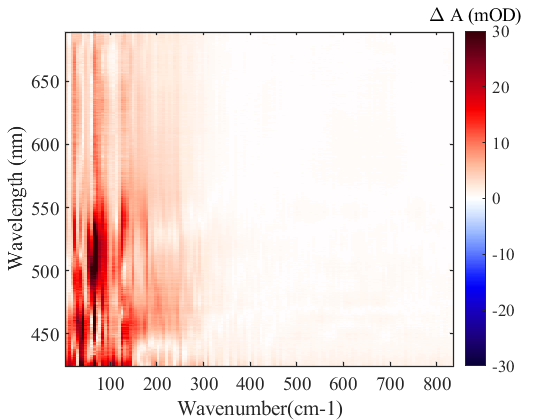

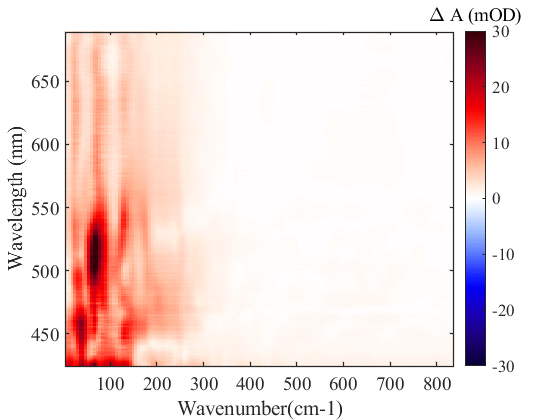

Global_Analysis=1;

 filt_med=1; %(Median filtering frequency domain data)

 tic
 
if Global_Analysis == 1
            
num_exp=5; %Choice for number of exponential
    
   irf=0.05;   %sigma for IRF=2.305*sigma (FWHM)
    %Input for exponential component 1
    
    a(1)=0.1;   %Time constant 1 in ps
    u(1)=1;    %Upper bound
    l(1)=irf;    %Lower bound
    
    %Input for exponential component 2
    
    a(2)=0.5;     %Time constant 2 in ps
    u(2)=100;     %Upper bound
    l(2)=irf;    %Lower bound
    
    %Input for exponential component 3
    
    a(3)=5;     %Time constant 3 in ps
    u(3)=Inf;    %Upper bound
    l(3)=irf;     %Lower bound
    
    %Input for exponential component 4
    
    a(4)=35;   %Time constant 4 in ps
    u(4)=Inf;  %Upper bound
    l(4)=irf;   %Lower bound
    
    %Input for exponential component 5
    
    a(5)=40000;   %Time constant 5 in ps
    u(5)=Inf;  %Upper bound
    l(5)=10000;   %Lower bound
    
    evol=4000;
    
    % time=timeDelays./1000;
    
    %Global Fitting using Levenberg-Marquardt algoritm
    options=optimoptions('lsqnonlin','Display','iter','MaxIterations',evol,'MaxFunctionEvaluations',evol);
    p=double(a(1:num_exp));
    ub=double(u(1:num_exp));
    lb=double(l(1:num_exp));
    fun =@(p) global_fit(p,time(1:del),filtA_corr(1:del,:),irf,num_exp,del);
    %fun = @(p) global_fit(p,time,filtA,irf,num_exp);
    param=lsqnonlin(fun,p,lb,ub,options);
    %param=lsqnonlin(fun,p,lb,ub);
    
    % %Confidence Interval calculation
    [beta,resnorm,resid,exitflag,output,lambda,J]=lsqnonlin(fun,p,lb,ub,options);
    ci=nlparci(beta,resid,'jacobian',J);
    
    s=0;
    for i=1:num_exp
        %c =0.5* param(2*i-1).*exp((-1*time)./param(2*i)).*exp(irf.^2./(2*param(2*i).^2)).*(1+erf((time-(irf.^2./param(2*i)))./(sqrt(2).*irf)));
        c(i,1:del) =0.5*exp((-1*time(1:del))./param(i)).*exp(irf^2./(2*param(i)^2)).*(1+erf((time(1:del)-(irf^2./param(i)))./(sqrt(2)*irf)));
        %c=0.5*exp((-1*time)./param(i));
    end
    c1=pinv(c);
    b=filtA_corr(1:del,:)'*c1;
    s=(b*c);
    for i=1:num_exp
        figure(9)
        %     plot(wavelengths(range),b','o');
        plot(wavelengths(range1),movmean(b(:,i)',10),'o','DisplayName',[num2str(param(i)) 'ps']);
        xlabel('Wavelength (nm)');ylabel('\Delta A (DAS)');
        hold on;
        legend ('show');
        figure(10)
        plot(time(1:del),c(i,:),'linewidth',3,'DisplayName',[num2str(param(i)) 'ps']);
        xlabel('Time (ps)');ylabel('\Delta A (DAS)');
        hold on;
        legend ('show');
        tau(i)=param(i);
    end
    
%         for i=1:2
%         figure(7)
%         %     plot(wavelengths(range),b','o');
%         plot(wavelengths(range1),movmean(b(:,i)',10),'o','DisplayName',[num2str(param(i)) 'ps']);
%         xlabel('Wavelength (nm)');ylabel('\Delta A (DAS)');
%         hold on;
%         legend ('show');
%         figure(8)
%         plot(time(1:len_comp-sub),c(i,:),'linewidth',3,'DisplayName',[num2str(param(i)) 'ps']);
%         hold on;
%         legend ('show');
%         tau(i)=param(i);
%     end
    
    tau;
       
    res=filtA_corr(1:del,:)-s';
    
    if filt_med==1
        filt_res=medfilt2(res,[3 3]);
    else
        filt_res=res;
    end
    
    timePoint=11;
     %res=filtA-s';
    ft_res=fft(filt_res(timePoint:del,:));
%     ft_resShft=fftshift(ft_res,1);
   
    del_t=(time(del)-time(timePoint))*1000;
%     del_t=20;
    diff=del-timePoint;
    omega=(1:diff/2).*(33357/del_t);
    
    filt_fftres=abs(ft_res);
    
    filt_fftres1=imgaussfilt(filt_fftres,1); %Gaussian filtering
  
    figure();
    imagesc(time(1:del),wavelengths(range1),s,[-20 20]);set(gcf,'color','w');set(gca,'fontname','times');set(gca,'FontSize',14,'linewidth',1);set(gca,'YDir','normal')
    xlabel('Time Delay (ps)');ylabel('Wavelength (nm)');
    colormap(CT);
    hcb=colorbar; title(hcb,'\Delta A (mOD)','fontsize',14,'fontname','times');set(hcb,'fontsize',13,'fontname','times','ylim', [-20 20]);
    
    figure();
    imagesc(time(1:del),wavelengths(range1),res',[-2 2]);set(gcf,'color','w');set(gca,'fontname','times');set(gca,'FontSize',14,'linewidth',1);set(gca,'YDir','normal')
    xlabel('Time Delay (ps)');ylabel('Wavelength (nm)');
    colormap(CT);
    hcb=colorbar; title(hcb,'\Delta A (mOD)','fontsize',14,'fontname','times');set(hcb,'fontsize',13,'fontname','times','ylim', [-2 2]);
    
    figure();
    imagesc(time(timePoint:del),wavelengths(range1),res(timePoint:del,:)',[-2 2]);set(gcf,'color','w');set(gca,'fontname','times');set(gca,'FontSize',14,'linewidth',1);set(gca,'YDir','normal')
    xlabel('Time Delay (ps)');ylabel('Wavelength (nm)');
    colormap(CT);
    hcb=colorbar; title(hcb,'\Delta A (mOD)','fontsize',14,'fontname','times');set(hcb,'fontsize',13,'fontname','times','ylim', [-2 2]);
    
    figure();
    imagesc(time(1:del),wavelengths(range1),filtA_corr(1:del,:)',[-20 20]);set(gcf,'color','w');set(gca,'fontname','times');set(gca,'FontSize',14,'linewidth',1);set(gca,'YDir','normal')
    xlabel('Time Delay (ps)');ylabel('Wavelength (nm)');
    colormap(CT);
    hcb=colorbar; title(hcb,'\Delta A (mOD)','fontsize',14,'fontname','times');set(hcb,'fontsize',13,'fontname','times','ylim', [-20 20]);
    
    figure();
    imagesc(omega,wavelengths(range1),filt_fftres(1:diff/2,:)',[-30 30]);set(gcf,'color','w');set(gca,'fontname','times');set(gca,'FontSize',14,'linewidth',1);set(gca,'YDir','normal')
    xlabel('Wavenumber(cm-1)');ylabel('Wavelength (nm)');
    colormap(CT);
    hcb=colorbar; title(hcb,'\Delta A (mOD)','fontsize',14,'fontname','times');set(hcb,'fontsize',13,'fontname','times','ylim', [-30 30]);
    
    figure();
    imagesc(omega,wavelengths(range1),filt_fftres1(1:diff/2,:)',[-30 30]);set(gcf,'color','w');set(gca,'fontname','times');set(gca,'FontSize',14,'linewidth',1);set(gca,'YDir','normal')
    xlabel('Wavenumber(cm-1)');ylabel('Wavelength (nm)');
    colormap(CT);
    hcb=colorbar; title(hcb,'\Delta A (mOD)','fontsize',14,'fontname','times');set(hcb,'fontsize',13,'fontname','times','ylim', [-30 30]);
    
    figure();
    imagesc(omega(1:80),wavelengths(range1),filt_fftres1(1:80,:)',[-30 30]);set(gcf,'color','w');set(gca,'fontname','times');set(gca,'FontSize',14,'linewidth',1);set(gca,'YDir','normal')
    xlabel('Wavenumber(cm-1)');ylabel('Wavelength (nm)');
    colormap(CT);
    hcb=colorbar; title(hcb,'\Delta A (mOD)','fontsize',14,'fontname','times');set(hcb,'fontsize',13,'fontname','times','ylim', [-30 30]);
       
end

toc

Elapsed time is 10.229847 seconds.



if Global_Analysis
    double(ci)
end

ans = 	1.0e+05 *

    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
   -2.6659    2.8659


# **Overlay Plot**

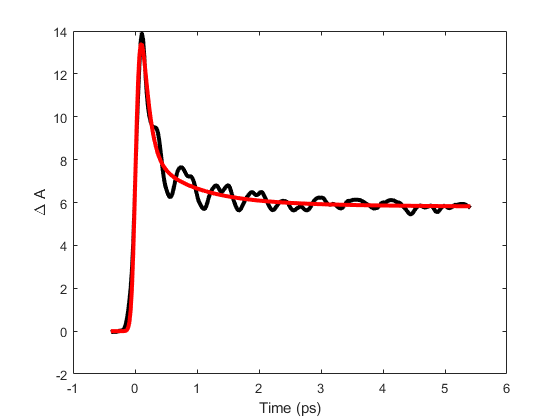

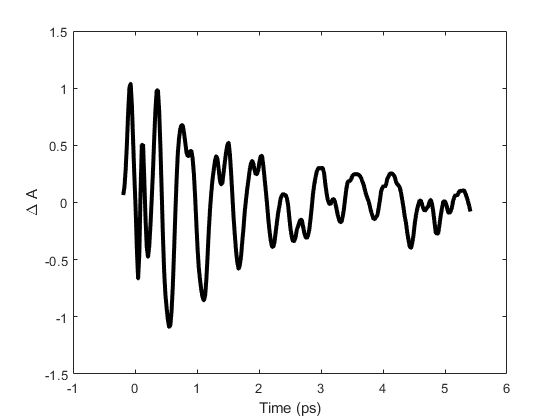

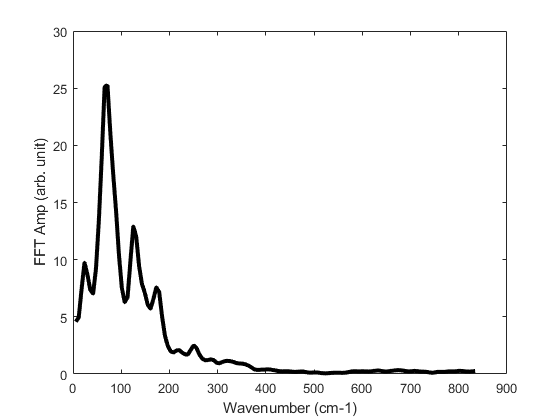

CurveFitting=1;

if CurveFitting==1
% wnln=zeroes(1:length(range1));
% wvln=0;
w=wavelengths(range1);
int_wavelength=530; %input wavelength for fitting
j = find(w<=int_wavelength,1,'last');
sum1=0;
sum2=0;
sum3=0;
k=0;

for i=j-10:j+10
    sum1=sum1+filtA_corr(1:del,j);
    sum2=sum2+res(1:del,j)';
    sum3=sum3+s(j,1:del)';
    k=k+1;
end

avg_trace=sum1/k; %average of ten traces around input wavelength
avg_res=sum2/k;
avg_s=sum3/k;
%avg_trace=sum1;
% Plotting the graphs
figure()
plot(time(1:del),avg_trace,'color','k','linewidth',3);
hold on;
plot(time(1:del),avg_s,'color','r','linewidth',3);
xlabel('Time (ps)');ylabel('\Delta A');
hold off;

figure()
plot(time(timePoint:del),avg_res(timePoint:del),'color','k','linewidth',3);
xlabel('Time (ps)');ylabel('\Delta A');

figure()
plot(omega(1:diff/2),filt_fftres1(1:diff/2,j)','color','k','linewidth',3);
xlabel('Wavenumber (cm-1)');ylabel('FFT Amp (arb. unit)');

end

## **Sequential Model**

seq_mod=0;

tic

if seq_mod
    
    
num_species=4; %Choice for number of exponential

num_exp=num_species;

irf=0.030;

evol=4000;

%Input for exponential component 1

a(1)=0.1;   %Time constant 1 in ps
u(1)=1000;    %Upper bound
l(1)=irf;    %Lower bound

%Input for exponential component 2

a(2)=1;     %Time constant 2 in ps
u(2)=10;     %Upper bound
l(2)=irf;    %Lower bound

%Input for exponential component 3

a(3)=5;     %Time constant 3 in ps
u(3)=Inf;    %Upper bound
l(3)=irf;     %Lower bound
%Input for exponential component 4

a(4)=15;   %Time constant 4 in ps
u(4)=100;  %Upper bound
l(4)=irf;   %Lower bound

%Input for exponential component 5

a(5)=400;   %Time constant 5 in ps
u(5)=1000;  %Upper bound
l(5)=irf;   %Lower bound

%filtA=sgolayfilt(g_abs(:,range),7,9);
%filtA=medfilt2(g_abs(:,range),[4 4]);

%Irf and Tzero
%IRF
% rn=range(end)-range(1)+1;
% 
% k=0;
% for i=1:1900
%     if (g_abs(:,i)==zeros(length(time)))
%         k=k;
%     else
%         k=k+1;
%         g2_abs(:,k)=g_abs(:,i);
%         wvln(k)= wavelengths(i);
%     end
% end
% g2_abs=g2_abs-0.6;

% len_comp=length(time);
% del=len_comp-sub;
%Global Fitting using Levenberg-Marquardt algoritm
options=optimoptions('lsqnonlin','Display','iter','MaxIterations',evol,'MaxFunctionEvaluations',evol);
p=double(a(1:num_exp));
ub=double(u(1:num_exp));
lb=double(l(1:num_exp));
fun = @(p) global_fit_seq(p,time(1:del),filtA_corr(1:del,:),irf,num_exp,del);
%fun = @(p) global_fit(p,time,filtA,irf,num_exp);
param1=lsqnonlin(fun,p,lb,ub,options);
%param=lsqnonlin(fun,p,lb,ub);

% %Confidence Interval calculation
[beta,resnorm,resid,exitflag,output,lambda,J]=lsqnonlin(fun,p,lb,ub,options);
ci1=nlparci(beta,resid,'jacobian',J);

% s=0;
% for i=1:num_exp
%  %c =0.5* param(2*i-1).*exp((-1*time)./param(2*i)).*exp(irf.^2./(2*param(2*i).^2)).*(1+erf((time-(irf.^2./param(2*i)))./(sqrt(2).*irf)));
%   c(i,:) =0.5*exp((-1*time(1:len_comp-sub))./param(i)).*exp(irf^2./(2*param(i)^2)).*(1+erf((time(1:len_comp-sub)-(irf^2./param(i)))./(sqrt(2)*irf)));
%  %c=0.5*exp((-1*time)./param(i));
% end
%  c1=pinv(c);
%  b=g2_abs(1:del,:)'*c1;
%  s=(b*c);
time=time(1:del);
s1=0;
i=1;
n=num_exp;
a=0;
par=1./param1;
for l=1:n
    s=0;
    for j=1:l
        if (l==1)
            a(j,l)=1;
            c(l,1:del) =a(j,l)*exp((-1*time)./param1(j)).*exp(irf^2./(2*param1(j)^2)).*(1+erf((time-(irf^2./param1(j)))./(sqrt(2)*irf)));
%             figure (5);
%             hold on;
%             plot(time,c(l,:),'o','DisplayName',[num2str(i)]);
%             legend ('show');
        else
            k_num=1;
            for m=1:l-1
                k_num=k_num*par(m);
            end
            k_den=1;
            for n1=1:l
                if (n1~=j)
                    k_den=k_den*(par(n1)-par(j));
                end
            end
            a(j,l)=k_num/k_den;
            c1(j,1:del)=a(j,l)*exp((-1*time)./param1(j)).*exp(irf^2./(2*param1(j)^2)).*(1+erf((time-(irf^2./param1(j)))./(sqrt(2)*irf)));
            s=s+c1(j,:);
%             figure (5);
%             hold on;
%             i=i+1;
%             plot(time,c1(j,:),'o','DisplayName',[num2str(i)]);
%             legend ('show');
        end
    end
    if (max(s)~=0)
        c(l,:)=s;
        figure (64);
        hold on
        plot(time,c(l,1:del),'linewidth', 3,'DisplayName',[num2str(param1(l)) 'ps']);
        xlabel('Time Delay (ps)');ylabel('\Delta A (EADS)');
        legend ('show');
    else
        figure(64);
        hold on;
        plot(time,c(1,1:del),'linewidth', 3,'DisplayName',[num2str(param1(l)) 'ps']);
        xlabel('Time Delay (ps)');ylabel('\Delta A (EADS)');
        legend ('show');
    end
end

c2=pinv(c);

b=filtA_corr(1:del,:)' * c2;

s1=(b*c);


for i=1:num_exp
    figure(48)
    %     plot(wavelengths(range),b','o');
    plot(wavelengths(range1),b(:,i)','o','DisplayName',[num2str(param1(i)) 'ps']);
    xlabel('Wavelength (nm)');ylabel('\Delta A (EADS)');
    hold on;
    legend ('show');
    %      figure(6)
    %      plot(time(1:len_comp-sub),c(i,:),'linewidth',3,'DisplayName',[num2str(param(i)) 'ps']);
    %      hold on;
    %      legend ('show');
    %      tau(i)=param(i);
end

% disp (tau);

res1=filtA_corr(1:del,:)-s1';

% if filt_med==1
%         filt_res=medfilt2(res,[3 3]);
%     else
        filt_res1=res1;
%     end
    
    timePoint=15;
     %res=filtA-s';
    ft_res1=fft(filt_res1(timePoint:del,:));
%     ft_resShft=fftshift(ft_res,1);
   
    del_t=(time(del)-time(timePoint))*1000;
%     del_t=20;
    diff=del-timePoint;
    omega=(1:diff/2).*(33357/del_t);
    
    filt_fftres2=abs(ft_res1);
    
    filt_fftres3=imgaussfilt(filt_fftres2,1);
%res=filtA-s';

figure();
imagesc(time(1:del),wavelengths(range1),s1,[-20 20]);set(gcf,'color','w');set(gca,'fontname','times');set(gca,'FontSize',14,'linewidth',1);set(gca,'YDir','normal')
xlabel('Time Delay (ps)');ylabel('Wavelength (nm)');
colormap(CT);
hcb=colorbar; title(hcb,'\Delta A (mOD)','fontsize',14,'fontname','times');set(hcb,'fontsize',13,'fontname','times','ylim', [-20 20]);

figure();
imagesc(time(timePoint:del),wavelengths(range1),res1(timePoint:del,:)',[-2 2]);set(gcf,'color','w');set(gca,'fontname','times');set(gca,'FontSize',14,'linewidth',1);set(gca,'YDir','normal')
xlabel('Time Delay (ps)');ylabel('Wavelength (nm)');
colormap(CT);
hcb=colorbar; title(hcb,'\Delta A (mOD)','fontsize',14,'fontname','times');set(hcb,'fontsize',13,'fontname','times','ylim', [-2 2]);

figure();
imagesc(time(1:del),wavelengths(range1),filtA_corr(1:del,:)',[-20 20]);set(gcf,'color','w');set(gca,'fontname','times');set(gca,'FontSize',14,'linewidth',1);set(gca,'YDir','normal')
xlabel('Time Delay (ps)');ylabel('Wavelength (nm)');
colormap(CT);
hcb=colorbar; title(hcb,'\Delta A (mOD)','fontsize',14,'fontname','times');set(hcb,'fontsize',13,'fontname','times','ylim', [-20 20]); 

figure();
    imagesc(omega(1:diff/2),wavelengths(range1),filt_fftres3(1:diff/2,:)',[-10 10]);set(gcf,'color','w');set(gca,'fontname','times');set(gca,'FontSize',14,'linewidth',1);set(gca,'YDir','normal')
    xlabel('Wavenumber(cm-1)');ylabel('Wavelength (nm)');
    colormap(CT);
    hcb=colorbar; title(hcb,'\Delta A (mOD)','fontsize',14,'fontname','times');set(hcb,'fontsize',13,'fontname','times','ylim', [-10 10]);

end

toc

Elapsed time is 0.002958 seconds.



 if seq_mod
   disp   (ci1);
 end

# **Wavelet Transformation**

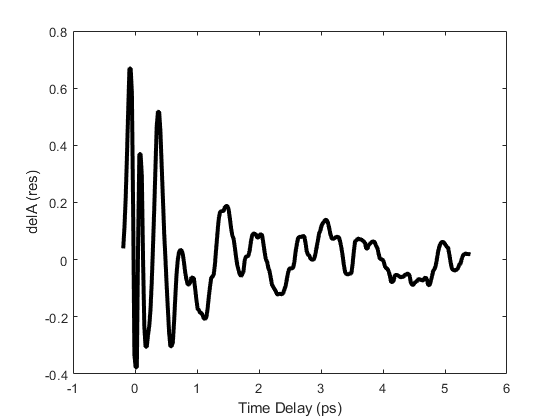

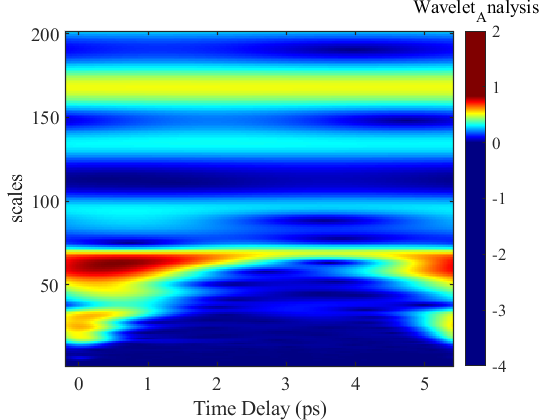

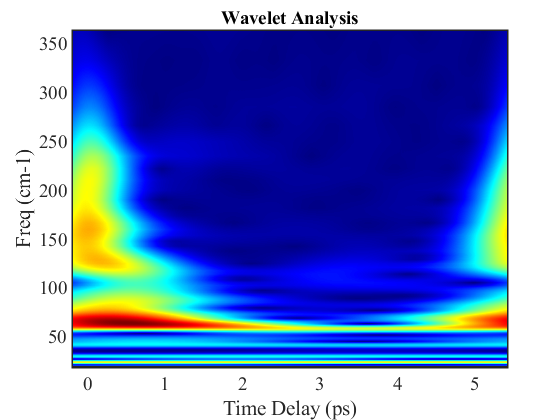

 WT=1;
 
 if WT
     
 subtract=0;
 nb_length=200;
 int_wavelength1=600; 
 centre_freq=15;
%  timePoint1=timePoint;
 
 if Global_Analysis==1
     wav_res=filt_res(timePoint:del,:);
 else
     wav_res=filt_res1(timePoint:del,:);
 end
  time_WT=time(timePoint:del);
 dt=timeDelays(2)-timeDelays(1); % sampling time
 wav_analysis=Wavelet_Analysis(wav_res,time_WT,dt,wavelengths,int_wavelength1,nb_length,subtract,centre_freq,range1);
 end

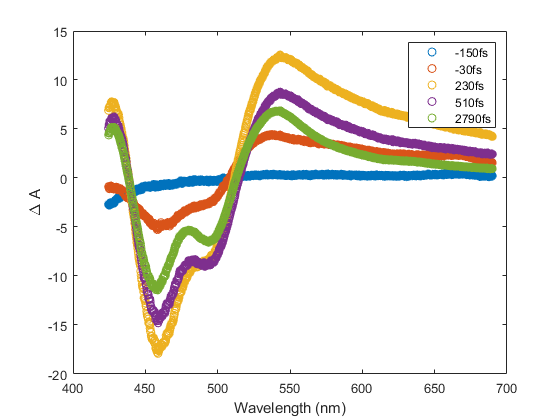

 timept=[13,19,32,46,160];
for itemp1 = 1:length(timept)
    figure(250)
    plot(wavelengths(range1),filtA_corr(timept(itemp1),:),'o','DisplayName',[num2str(time(timept(itemp1))*1000) 'fs']);
    xlabel('Wavelength (nm)');ylabel('\Delta A');
    legend ('show');
    hold on;
end

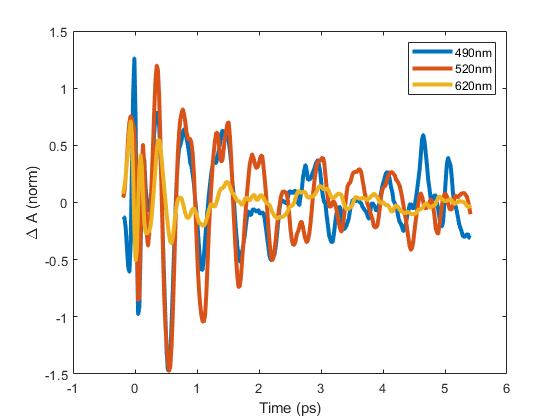


wavpt=[490,520,620];
% Osc_mult=[1,1,1];
% timept1=19;
for itemp2 = 1:length(wavpt)
%     int_wavelength=515; %input wavelength for fitting
j = find(w<=wavpt(itemp2),1,'last');
sum4=0;
k1=0;

for i=j-10:j+10
    
    sum4=sum4+res(timePoint:del,j);
 
    k1=k1+1;
end

avg_res1=sum4/k1;

    figure(285)
    plot(time(timePoint:del),avg_res1,'-','linewidth', 3,'DisplayName',[num2str(wavpt(itemp2)) 'nm']);
    xlabel('Time (ps)');ylabel('\Delta A (norm)');
    legend ('show');
    hold on;
end

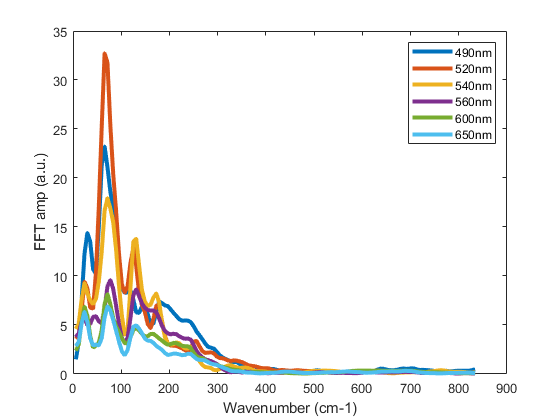

wavpt1=[490,520,540,560,600,650];
% Osc_mult=[1.2,1];
%timept1=19;
for itemp3 = 1:length(wavpt1)
%     int_wavelength=515; %input wavelength for fitting
j = find(w<=wavpt1(itemp3),1,'last');
sum6=0;
k1=0;

for i=j-10:j+10
    
    sum6=sum6+filt_fftres1(:,j);
 
    k1=k1+1;
end

avg_fft=sum6/k1;

    figure(292)
    plot(omega(1:diff/2),avg_fft(1:diff/2),'-','linewidth', 3,'DisplayName',[num2str(wavpt1(itemp3)) 'nm']);
    xlabel('Wavenumber (cm-1)');ylabel('FFT amp (a.u.)');
    legend ('show');
    hold on;
end

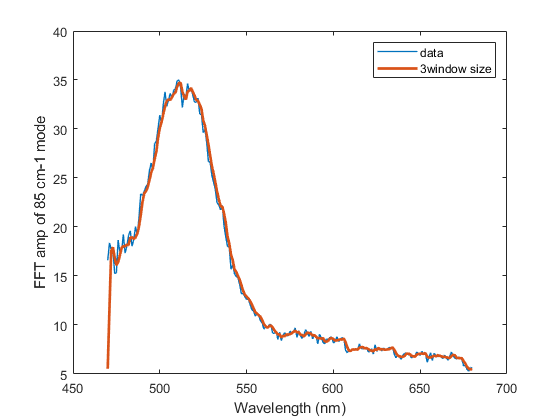

wavpt2=470:1:680;

pt=zeros(1,length(wavpt2));

for itemp4=1:length(wavpt2)

j = find(w<=wavpt2(itemp4),1,'last');   
    
sum6=0;

k1=0;

for i=j-5:j+5
    
    sum6=sum6+filt_fftres1(:,j);
 
    k1=k1+1;
end

avg_fft=sum6/k1;

pt(itemp4)=max(avg_fft);
% max_pt(itemp4)=max(avg_fft);
 
end

% codegen averaging_filter -args {pt}
windowSize = 3; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;
filter_pt = filter(b,a,pt);

figure()
plot(wavpt2,pt,'-','linewidth',1,'DisplayName','data');
hold on;
plot(wavpt2,filter_pt,'-','linewidth', 2,'DisplayName',[num2str(windowSize) 'window size']);
hold off;
xlabel('Wavelength (nm)');ylabel('FFT amp of 85 cm-1 mode');
legend (gca,'show');
hold on;

% 

# **Oscillation fitting**

    wav=wavelengths(range1);
    int_wavelength2=600;
    
    j = find(wav<=int_wavelength2,1,'last');
    sum1=0;
    sum7=0;
    k=0;
            
    for i=j-10:j+10
        sum1=sum1+filt_res(timePoint:del,j);
        sum7=sum7+filt_fftres1(:,j);
        k=k+1;
    end   
    
    res_fit=sum1/k;
    
    num_freq=9; %Choice for number of exponential

% num_exp=num_species;
% for i=j-10:j+10
%     
%     
%  
%     k1=k1+1;
% end

avg_fft_real=sum7/k;

% irf=0.030;

evol=4000;

%Input for freq component 1

f(1)=0.1;   % Amplitude
f(2)=300;   % Freq 1 in cm-1
f(3)=0.5;   % Time constant (dephasing) in ps
f(4)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(1)=1000;    
l(1)=0.01;
u(2)=500;    
l(2)=5;
u(3)=10;    
l(3)=-10;
u(4)=10*pi;    
l(4)=0.001;

%Input for freq component 2

f(5)=0.1;   % Amplitude
f(6)=250;   % Freq 1 in cm-1
f(7)=0.5;   % Time constant (dephasing) in ps
f(8)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(5)=1000;    
l(5)=0.01;
u(6)=500;    
l(6)=5;
u(7)=10;    
l(7)=-10;
u(8)=10*pi;    
l(8)=0.001;

%Input for freq component 3

f(9)=0.1;   % Amplitude
f(10)=180;   % Freq 1 in cm-1
f(11)=0.5;   % Time constant (dephasing) in ps
f(12)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(9)=1000;    
l(9)=0.01;
u(10)=500;    
l(10)=5;
u(11)=10;    
l(11)=-10;
u(12)=10*pi;    
l(12)=0.001;

%Input for freq component 4

f(13)=0.1;   % Amplitude
f(14)=120;   % Freq 1 in cm-1
f(15)=0.5;   % Time constant (dephasing) in ps
f(16)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(13)=1000;    
l(13)=0.01;
u(14)=500;    
l(14)=5;
u(15)=10;    
l(15)=-10;
u(16)=10*pi;    
l(16)=0.001;

%Input for freq component 5

f(17)=0.1;   % Amplitude
f(18)=80;   % Freq 1 in cm-1
f(19)=0.5;   % Time constant (dephasing) in ps
f(20)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(17)=1000;    
l(17)=0.01;
u(18)=500;    
l(18)=5;
u(19)=10;    
l(19)=-10;
u(20)=10*pi;    
l(20)=0.001;

%Input for freq component 6

f(21)=0.1;   % Amplitude
f(22)=60;   % Freq 1 in cm-1
f(23)=0.5;   % Time constant (dephasing) in ps
f(24)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(21)=1000;    
l(21)=0.01;
u(22)=500;    
l(22)=5;
u(23)=10;    
l(23)=-10;
u(24)=10*pi;    
l(24)=0.001;

%Input for freq component 7

f(25)=0.1;   % Amplitude
f(26)=45;   % Freq 1 in cm-1
f(27)=0.5;   % Time constant (dephasing) in ps
f(28)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(25)=1000;    
l(25)=0.01;
u(26)=500;    
l(26)=5;
u(27)=10;    
l(27)=-10;
u(28)=10*pi;    
l(28)=0.001;

%Input for freq component 8

f(29)=0.1;   % Amplitude
f(30)=30;   % Freq 1 in cm-1
f(31)=0.5;   % Time constant (dephasing) in ps
f(32)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(29)=1000;    
l(29)=0.01;
u(30)=500;    
l(30)=5;
u(31)=10;    
l(31)=-10;
u(32)=10*pi;    
l(32)=0.001;

%Input for freq component 9

f(33)=0.1;   % Amplitude
f(34)=130;   % Freq 1 in cm-1
f(35)=0.5;   % Time constant (dephasing) in ps
f(36)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(33)=1000;    
l(33)=0.01;
u(34)=500;    
l(34)=5;
u(35)=10;    
l(35)=-10;
u(36)=10*pi;    
l(36)=0.001;

%Input for freq component 10

f(37)=0.1;   % Amplitude
f(38)=150;   % Freq 1 in cm-1
f(39)=0.5;   % Time constant (dephasing) in ps
f(40)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(37)=1000;    
l(37)=0.01;
u(38)=500;    
l(38)=5;
u(39)=10;    
l(39)=-10;
u(40)=10*pi;    
l(40)=0.001;

options=optimoptions('lsqcurvefit','Display','iter','MaxIterations',evol,'MaxFunctionEvaluations',evol);
b=double(f(1:num_freq*4));
ub=double(u(1:num_freq*4));
lb=double(l(1:num_freq*4));
fun = @(p,t) freq_fit(p,t,num_freq);
tic
param=lsqcurvefit(fun,b,time_WT,res_fit.',lb,ub,options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0         37         5.62415                            71
     1         74         5.62415        3.61279             71      
     2        111         4.38931       0.903198       1.49e+03      
     3        148         3.39289       0.835052       2.45e+03      
     4        185         3.39289         1.8064       2.45e+03      
     5        222         3.06949     0.00317898            441      
     6        259         2.88715       0.451599       1.23e+03      
     7        296         2.39083       0.451599            576      
     8        333         1.49395       0.903198            685      
     9        370         1.49395        1.37654            685      
    10        407         1.29621       0.344136            238      
    11        444         1.21368       0.688272            389      
    12        481         1.0305

toc

Elapsed time is 0.784462 seconds.


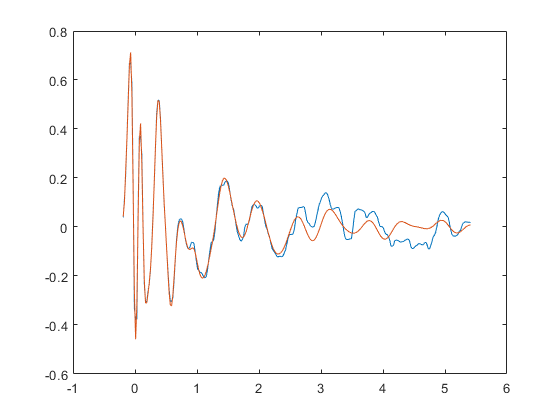

%lsqnonlin
for i=1:num_freq
    
    amp_fit(i)=param((4*i)-3);
    freq(i)=param((4*i)-2);
    tau(i)=param((4*i)-1);
    phase(i)=param((4*i));
    
end

fn=0;
for i=1:num_freq
    comp=param((4*i)-3).*exp(-time_WT./param((4*i)-1)).*sin((2*pi*(param((4*i)-2)*3*10^-2).*time_WT)+param((4*i)));
    Harm(i,:)=comp;
    fn=fn+comp;
end

figure()
plot(time_WT,res_fit);
hold on;
plot(time_WT,fn);
hold off;

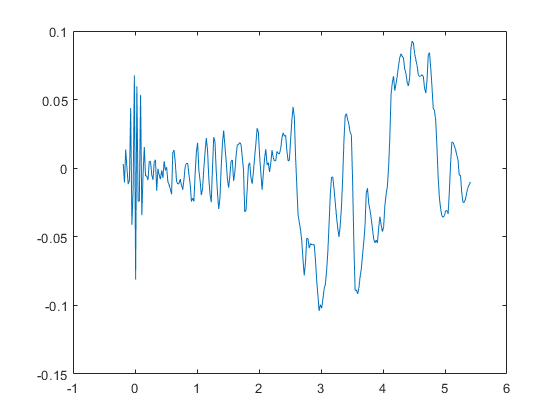

figure()
plot(time_WT,fn-res_fit.');

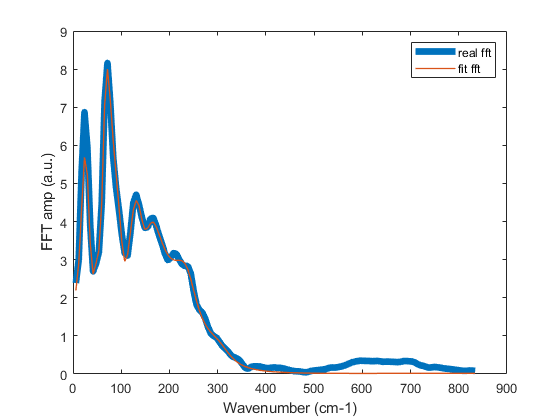

fit_fft=imgaussfilt(abs(fft(fn)),1);
figure()
 plot(omega(1:diff/2),avg_fft_real(1:diff/2),'-','linewidth', 5,'DisplayName','real fft');
 hold on;
 plot(omega(1:diff/2),fit_fft(1:diff/2),'-','linewidth', 1,'DisplayName','fit fft');
 hold off;
    xlabel('Wavenumber (cm-1)');ylabel('FFT amp (a.u.)');
    legend ('show');

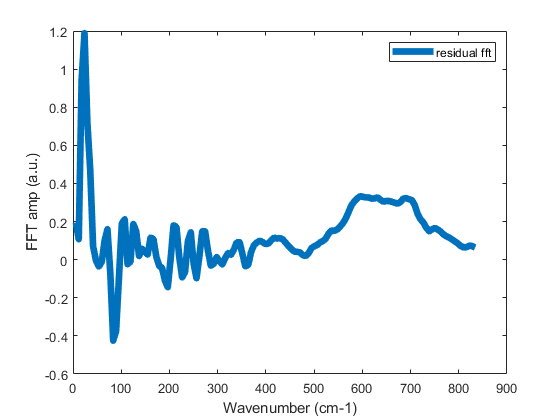

  ss=avg_fft_real(1:diff/2).'-fit_fft(1:diff/2);
    figure()
 plot(omega(1:diff/2),ss,'-','linewidth', 5,'DisplayName','residual fft');
     xlabel('Wavenumber (cm-1)');ylabel('FFT amp (a.u.)');
    legend ('show');

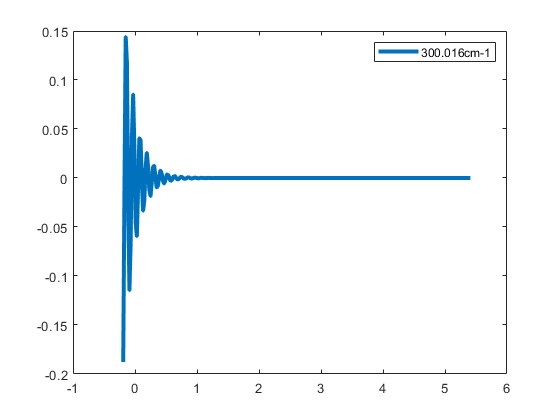

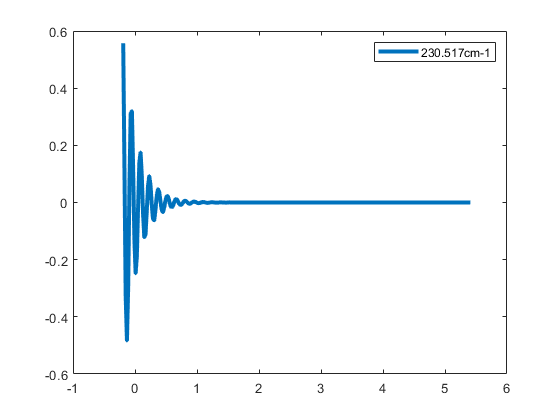

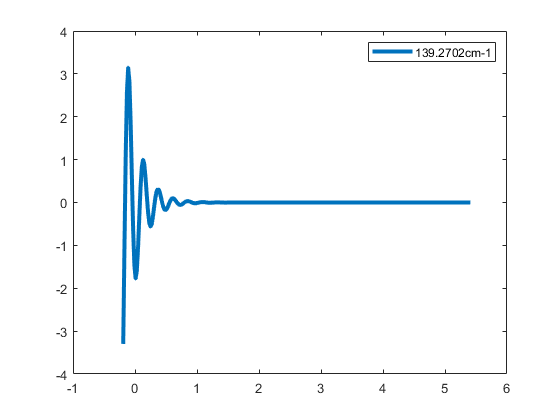

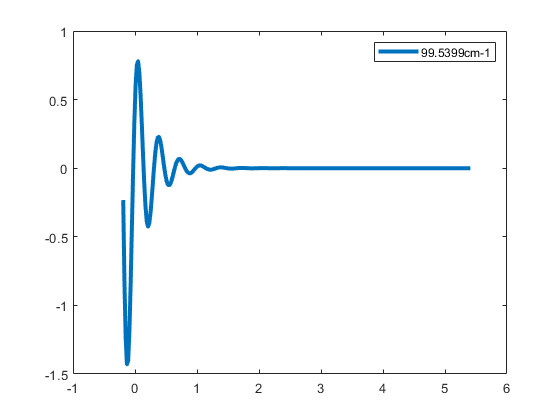

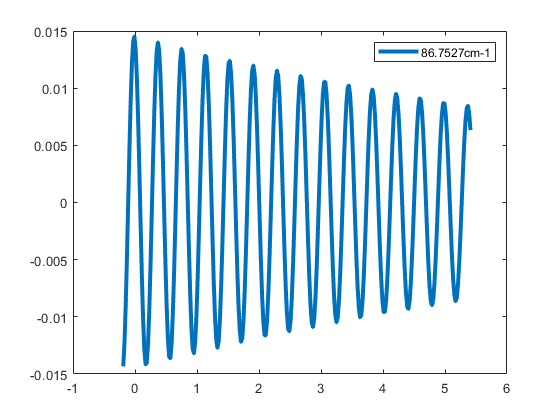

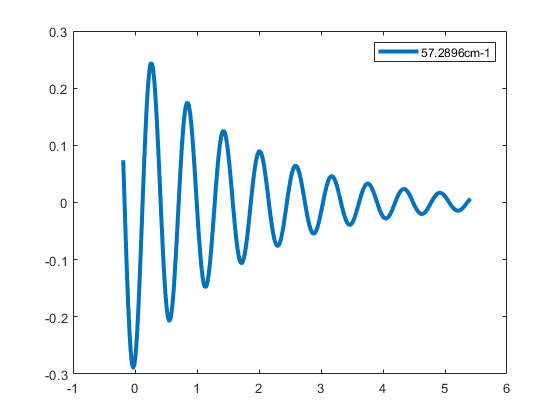

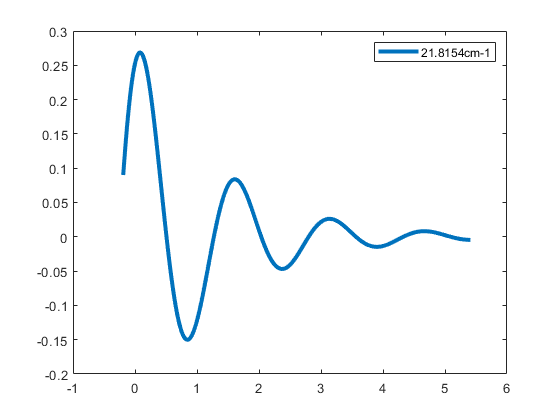

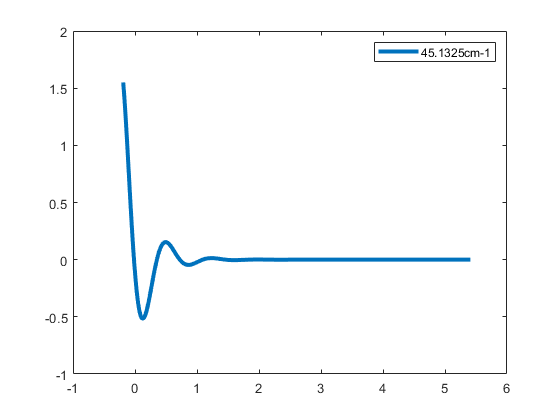

    
for ii=1:num_freq
figure()
    plot(time_WT,Harm(ii,:),'-','linewidth', 3,'DisplayName',[num2str(freq(ii)) 'cm-1']);
legend('show');
end


    amp_fit

amp_fit =     0.0725    0.2665    1.9110    0.9399    0.0145    0.2851    0.2909    0.8353    1.2252


    freq

freq =   300.0160  230.5170  139.2702   99.5399   86.7527   57.2896   21.8154   45.1325  140.2959


    tau

tau =     0.1845    0.2183    0.2087    0.2750    9.9751    1.7456    1.3125    0.3052    0.2894


    phase

phase =     3.2799    4.0475    4.2202    6.8306    1.7930    4.9587    7.3357    3.2808    1.1925


# **Tukey Window for filtering for region I**

      wav=wavelengths(range1);
    int_wavelength2=600;
    
    j = find(wav<=int_wavelength2,1,'last');
    sum1=0;
    sum7=0;
    k=0;
            
    for i=j-10:j+10
        sum1=sum1+filt_res(timePoint:del,j);
        sum7=sum7+filt_fftres1(:,j);
        k=k+1;
    end   
    
    res_fit=sum1/k;
 
 resolutn=10^2/((time_WT(end)-time_WT(1))*3); % resolution in frequency domain in cm-1 

% choose the frequency range of the filter look back on the omega variable
index=1;
freq(1)=omega(index);

% chose the number of steps, will set the range of the filter (N*resolutn)

N=33

N = 33

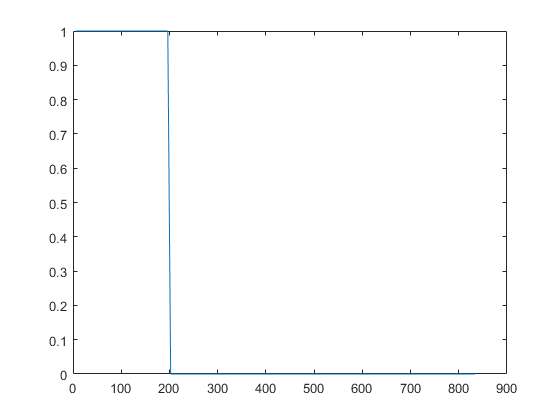


for ii=2:N
    freq(ii)=freq(ii-1)+resolutn;
end

% freq   %% frequency range

al=1/8; %% tapered cosine factor

% omega_new(1:index-1)=0;
% omega_new(index:index+N-1)=tukeywin(N,al);
% omega_new(index+N:length(omega))=0;
% omega_new1=fliplr(omega_new);

omega_new(index:index+N-1)=1;
omega_new(index+N:length(omega))=0;
omega_new1=fliplr(omega_new);

a=0;
omega_newf=cat(2,omega_new,a,omega_new1);

plot(omega,omega_new)

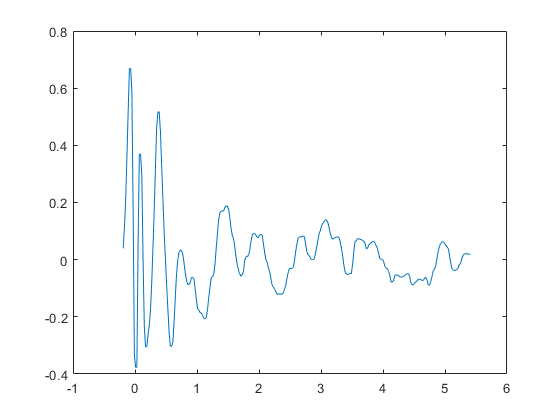

plot(time_WT,res_fit)

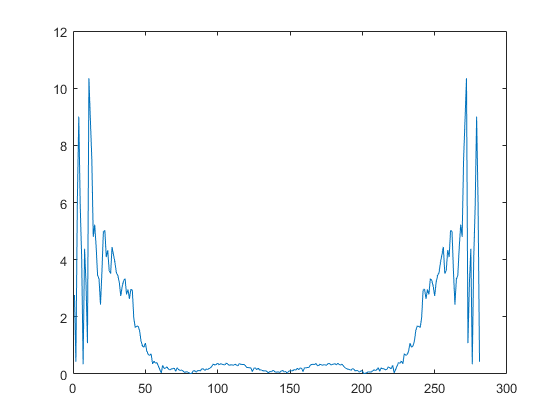

ft_plot=(fft(res_fit));
        plot(1:length(time_WT),abs(ft_plot));

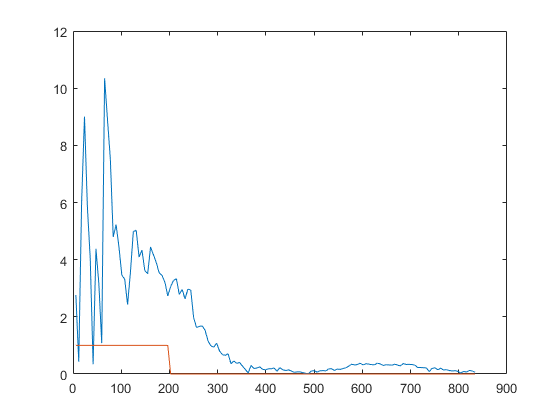

       gh=abs(ft_plot);
        plot(omega,gh(1:diff/2))
        hold on;
        plot(omega,omega_new)
        hold off;

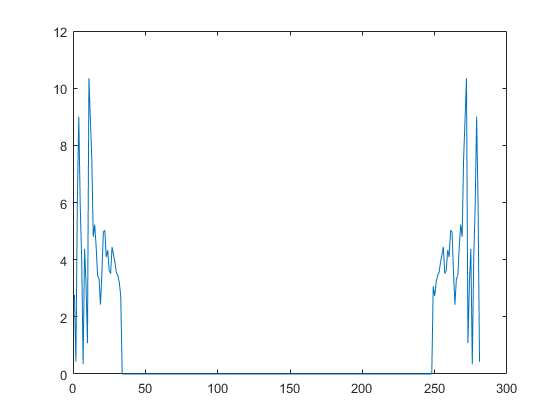

kk1=(ft_plot.').*omega_newf;
  plot(1:length(time_WT),abs(kk1));

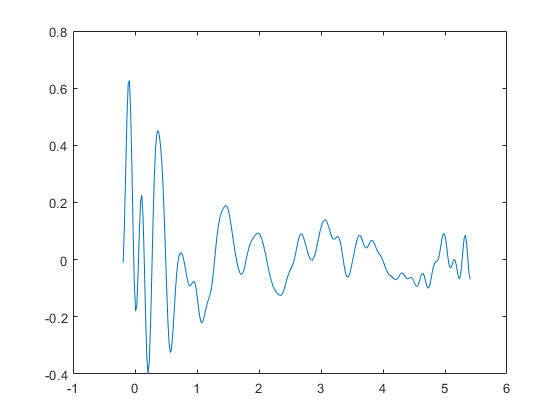

  kk_time1=ifft(kk1);
  plot(time_WT,real(kk_time1))

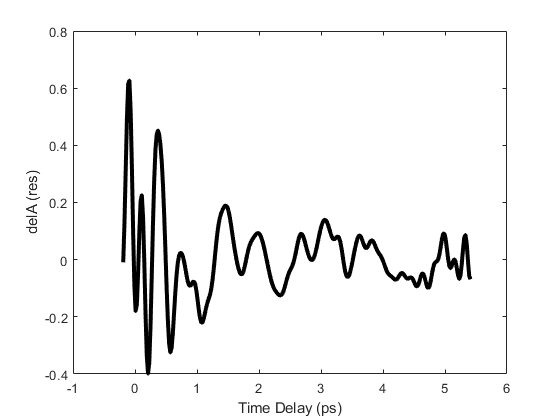

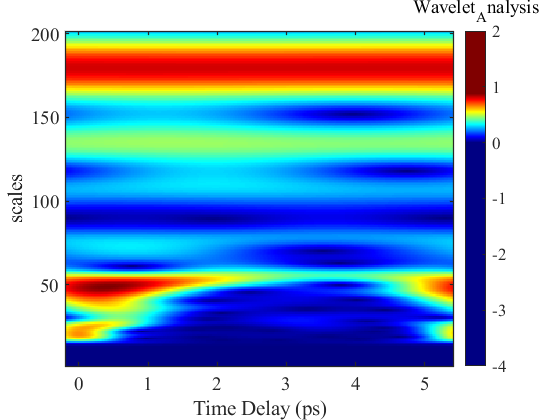

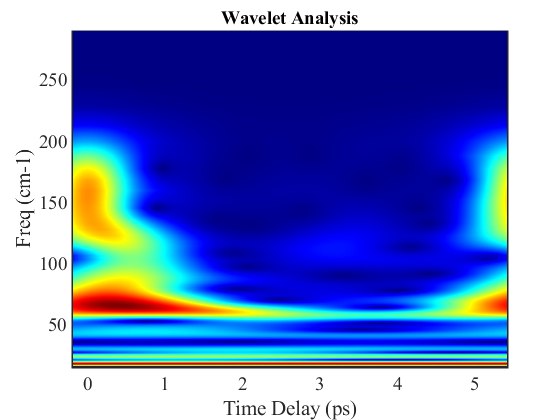

 subtract=0;
 nb_length=200;
 
 centre_freq=12;

     wav_res=real(kk_time1);

 wav_analysis=Wavelet_Analysis1(wav_res,time_WT,dt,nb_length,subtract,centre_freq);

# **Tukey Window for filtering for region II**

resolutn=10^2/((time_WT(end)-time_WT(1))*3); % resolution in frequency domain in cm-1 

% choose the frequency range of the filter look back on the omega variable
index=34;
freq(1)=omega(index);

% chose the number of steps, will set the range of the filter (N*resolutn)

N=48

N = 48

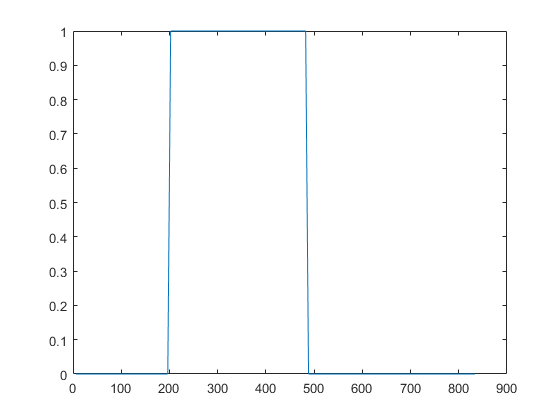


for ii=2:N
    freq(ii)=freq(ii-1)+resolutn;
end

% freq   %% frequency range

% al=1/9; %% tapered cosine factor

omega_new(1:index-1)=0;
% omega_new(index:index+N-1)=tukeywin(N,al);
% omega_new(index+N:length(omega))=0;
% omega_new1=fliplr(omega_new);

omega_new(index:index+N-1)=1;
omega_new(index+N:length(omega))=0;
omega_new1=fliplr(omega_new);

a=0;
omega_newf=cat(2,omega_new,a,omega_new1);

plot(omega,omega_new)

plot(time_WT,res_fit)

ft_plot=(fft(res_fit));
        plot(1:length(time_WT),abs(ft_plot));

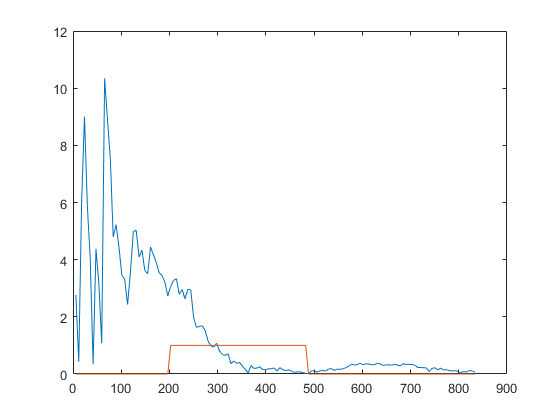

       gh=abs(ft_plot);
        plot(omega,gh(1:diff/2))
        hold on;
        plot(omega,omega_new)
        hold off;

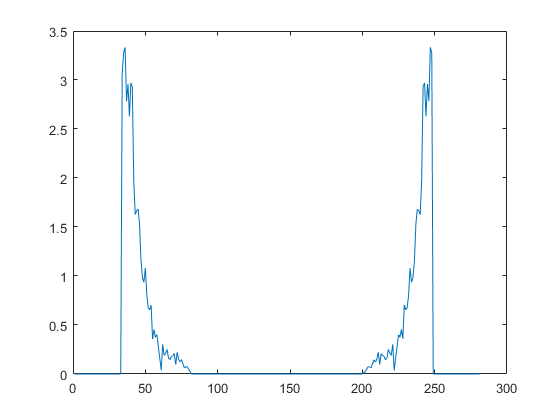

kk2=(ft_plot.').*omega_newf;
  plot(1:length(time_WT),abs(kk2));

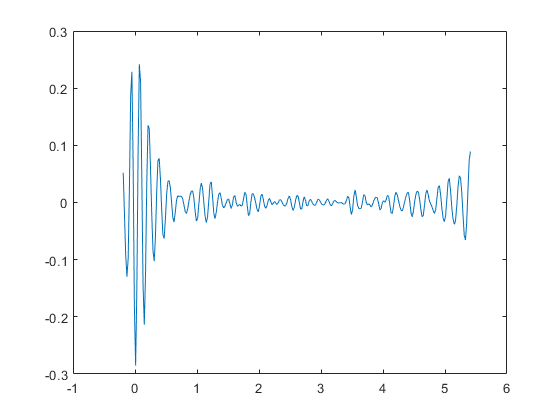

  kk_time2=ifft(kk2);
  plot(time_WT,real(kk_time2))

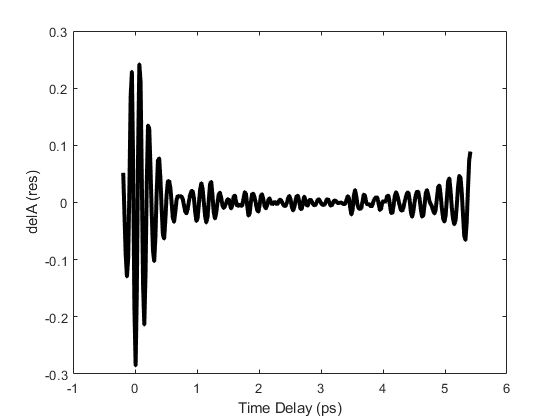

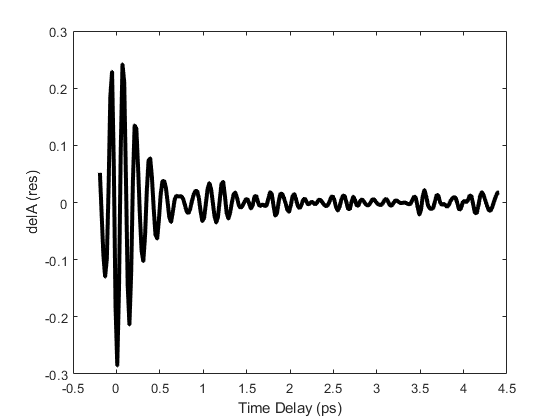

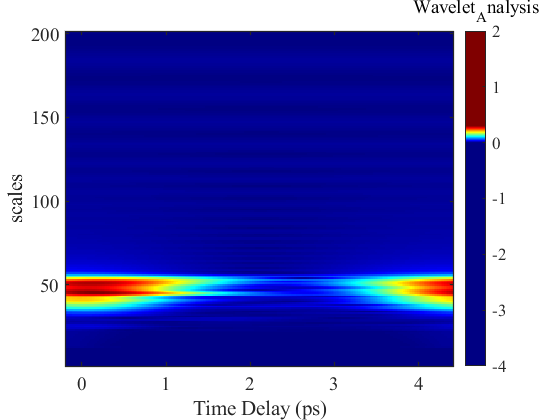

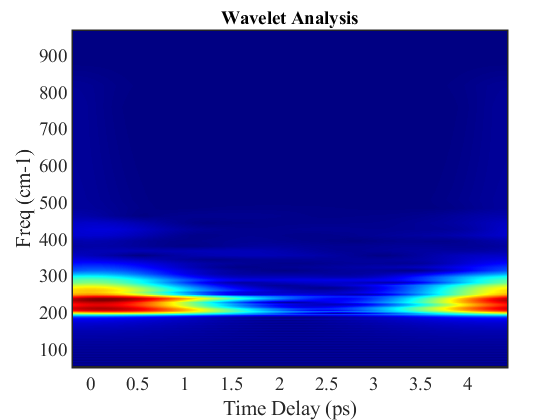

 subtract=50;
 nb_length=200;
 
 centre_freq=40;

     wav_res=real(kk_time2);

 wav_analysis=Wavelet_Analysis1(wav_res,time_WT,dt,nb_length,subtract,centre_freq);

# **Tukey Window for filtering for region III**

% resolutn=10^2/((time_WT(end)-time_WT(1))*3); % resolution in frequency domain in cm-1 
% 
% % choose the frequency range of the filter look back on the omega variable
% index=67;
% freq(1)=omega(index);
% 
% % chose the number of steps, will set the range of the filter (N*resolutn)
% 
% N=27
% 
% for ii=2:N
%     freq(ii)=freq(ii-1)+resolutn;
% end
% 
% % freq   %% frequency range
% 
% al=1/100; %% tapered cosine factor
% 
% omega_new(1:index-1)=0;
% % omega_new(index:index+N-1)=tukeywin(N,al);
% % omega_new(index+N:length(omega))=0;
% % omega_new1=fliplr(omega_new);
% 
% omega_new(index:index+N-1)=1;
% omega_new(index+N:length(omega))=0;
% omega_new1=fliplr(omega_new);
% a=0;
% omega_newf=cat(2,omega_new,a,omega_new1);
% 
% plot(omega,omega_new)
% plot(time_WT,res_fit)
% ft_plot=(fft(res_fit));
%         plot(1:length(time_WT),abs(ft_plot));
%        gh=abs(ft_plot);
%         plot(omega,gh(1:diff/2))
%         hold on;
%         plot(omega,omega_new)
%         hold off;
% kk3=(ft_plot.').*omega_newf;
%   plot(1:length(time_WT),abs(kk3));
%   kk_time3=ifft(kk3);
%   plot(time_WT,real(kk_time3))
%  subtract=5;
%  nb_length=200;
%  
%  centre_freq=40;
% 
%      wav_res=real(kk_time3);
% 
%  wav_analysis=Wavelet_Analysis1(wav_res,time_WT,dt,nb_length,subtract,centre_freq);

# **Tukey Window for filtering for region IV**

% resolutn=10^2/((time_WT(end)-time_WT(1))*3); % resolution in frequency domain in cm-1 
% 
% % choose the frequency range of the filter look back on the omega variable
% index=14;
% freq(1)=omega(index);
% 
% % chose the number of steps, will set the range of the filter (N*resolutn)
% 
% N=21
% 
% for ii=2:N
%     freq(ii)=freq(ii-1)+resolutn;
% end
% 
% % freq   %% frequency range
% 
% al=1/8; %% tapered cosine factor
% 
%  omega_new(1:index-1)=0;
% % omega_new(index:index+N-1)=tukeywin(N,al);
% % omega_new(index+N:length(omega))=0;
% % omega_new1=fliplr(omega_new);
% 
% omega_new(index:index+N-1)=1;
% omega_new(index+N:length(omega))=0;
% omega_new1=fliplr(omega_new);
% 
% a=0;
% omega_newf=cat(2,omega_new,a,omega_new1);
% 
% plot(omega,omega_new)
% plot(time_WT,res_fit)
% ft_plot=(fft(res_fit));
%         plot(1:length(time_WT),abs(ft_plot));
%        gh=abs(ft_plot);
%         plot(omega,gh(1:diff/2))
%         hold on;
%         plot(omega,omega_new)
%         hold off;
% kk4=(ft_plot.').*omega_newf;
%   plot(1:length(time_WT),abs(kk4));
%   kk_time4=ifft(kk4);
%   plot(time_WT,real(kk_time4))
%  subtract=0;
%  nb_length=200;
%  
%  centre_freq=20;
% 
%      wav_res=real(kk_time4);
% 
%  wav_analysis=Wavelet_Analysis1(wav_res,time_WT,dt,nb_length,subtract,centre_freq);


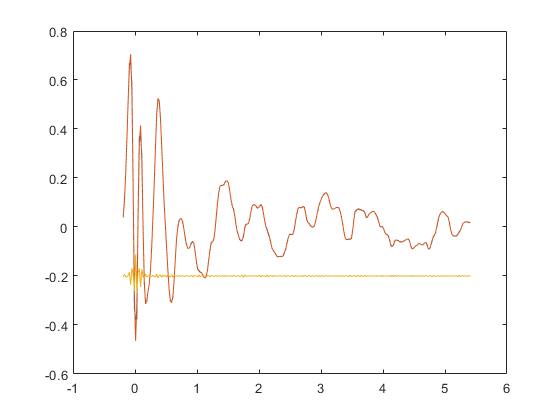

fit_regions=real(kk_time1+kk_time2);
res_regions=res_fit.'-fit_regions;

plot(time_WT,res_fit);
hold on;
plot(time_WT,fit_regions);
hold on
plot(time_WT,res_regions-0.2);
hold off

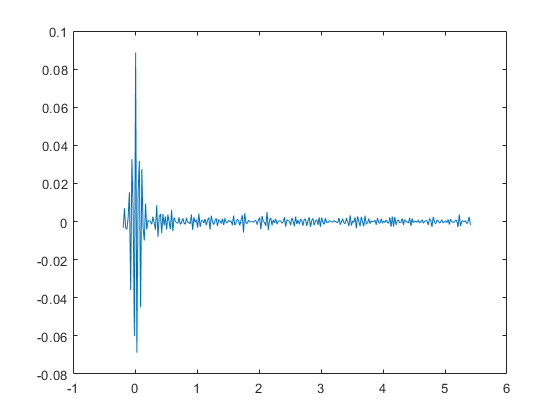


plot(time_WT,res_regions);

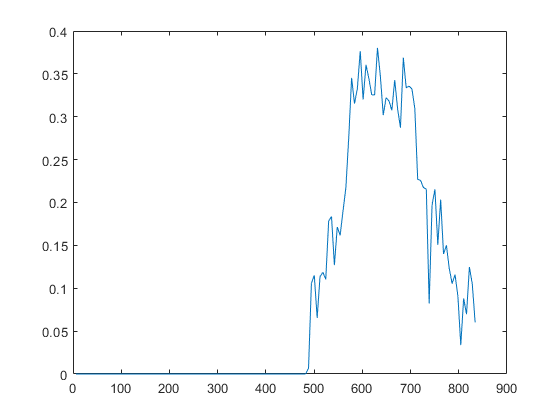

xxx=abs(fft(res_regions));

plot(omega(1:diff/2),xxx(1:diff/2));

plot(time_WT,real(kk_time1));

plot(time_WT,real(kk_time2));

% plot(time_WT,real(kk_time3));
% plot(time_WT,real(kk_time4));

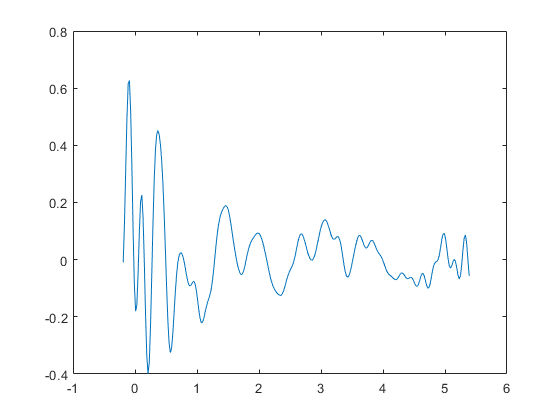

subst=00;
    diff1=length(kk_time1)-subst-1;
    res_fit_osc=real(kk_time1(1:diff1));
  time_WT1=time_WT(1:diff1); 
  avg_fft_real=abs(fft(kk_time1(1:end-subst))); 
  plot(time_WT1,res_fit_osc);

  del_t1=(time_WT1(end)-time_WT1(1))*1000;
  omega1=(1:diff1/2).*(33357/del_t1);

    num_freq=8; %Choice for number of exponential

% num_exp=num_species;
% for i=j-10:j+10
%     
%     
%  
%     k1=k1+1;
% end



% irf=0.030;

evol=4000;

%Input for freq component 1

f(1)=0.1;   % Amplitude
f(2)=25;   % Freq 1 in cm-1
f(3)=0.5;   % Time constant (dephasing) in ps
f(4)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(1)=1000;    
l(1)=0.01;
u(2)=500;    
l(2)=5;
u(3)=10;    
l(3)=-10;
u(4)=10*pi;    
l(4)=0.001;

%Input for freq component 2

f(5)=0.1;   % Amplitude
f(6)=50;   % Freq 1 in cm-1
f(7)=0.5;   % Time constant (dephasing) in ps
f(8)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(5)=1000;    
l(5)=0.01;
u(6)=500;    
l(6)=5;
u(7)=10;    
l(7)=-10;
u(8)=10*pi;    
l(8)=0.001;

%Input for freq component 3

f(9)=0.1;   % Amplitude
f(10)=65;   % Freq 1 in cm-1
f(11)=0.5;   % Time constant (dephasing) in ps
f(12)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(9)=1000;    
l(9)=0.01;
u(10)=500;    
l(10)=5;
u(11)=10;    
l(11)=-10;
u(12)=10*pi;    
l(12)=0.001;

%Input for freq component 4

f(13)=0.1;   % Amplitude
f(14)=80;   % Freq 1 in cm-1
f(15)=0.5;   % Time constant (dephasing) in ps
f(16)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(13)=1000;    
l(13)=0.01;
u(14)=500;    
l(14)=5;
u(15)=10;    
l(15)=-10;
u(16)=10*pi;    
l(16)=0.001;

%Input for freq component 5

f(17)=0.1;   % Amplitude
f(18)=125;   % Freq 1 in cm-1
f(19)=0.5;   % Time constant (dephasing) in ps
f(20)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(17)=1000;    
l(17)=0.01;
u(18)=500;    
l(18)=5;
u(19)=10;    
l(19)=-10;
u(20)=10*pi;    
l(20)=0.001;

%Input for freq component 6

f(21)=0.1;   % Amplitude
f(22)=150;   % Freq 1 in cm-1
f(23)=0.5;   % Time constant (dephasing) in ps
f(24)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(21)=1000;    
l(21)=0.01;
u(22)=500;    
l(22)=5;
u(23)=10;    
l(23)=-10;
u(24)=10*pi;    
l(24)=0.001;

%Input for freq component 7

f(25)=0.1;   % Amplitude
f(26)=180;   % Freq 1 in cm-1
f(27)=0.5;   % Time constant (dephasing) in ps
f(28)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(25)=1000;    
l(25)=0.01;
u(26)=500;    
l(26)=5;
u(27)=10;    
l(27)=-10;
u(28)=10*pi;    
l(28)=0.001;

%Input for freq component 8

f(29)=0.1;   % Amplitude
f(30)=35;   % Freq 1 in cm-1
f(31)=0.5;   % Time constant (dephasing) in ps
f(32)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(29)=1000;    
l(29)=0.01;
u(30)=500;    
l(30)=5;
u(31)=10;    
l(31)=-10;
u(32)=10*pi;    
l(32)=0.001;

%Input for freq component 9

f(33)=0.1;   % Amplitude
f(34)=35;   % Freq 1 in cm-1
f(35)=0.5;   % Time constant (dephasing) in ps
f(36)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(33)=1000;    
l(33)=0.01;
u(34)=500;    
l(34)=5;
u(35)=10;    
l(35)=-10;
u(36)=10*pi;    
l(36)=0.001;

%Input for freq component 10

f(37)=0.1;   % Amplitude
f(38)=35;   % Freq 1 in cm-1
f(39)=0.5;   % Time constant (dephasing) in ps
f(40)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(37)=1000;    
l(37)=0.01;
u(38)=500;    
l(38)=5;
u(39)=10;    
l(39)=-10;
u(40)=10*pi;    
l(40)=0.001;

%Input for freq component 11

f(41)=0.1;   % Amplitude
f(42)=50;   % Freq 1 in cm-1
f(43)=0.5;   % Time constant (dephasing) in ps
f(44)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(41)=1000;    
l(41)=0.01;
u(42)=500;    
l(42)=5;
u(43)=10;    
l(43)=-10;
u(44)=10*pi;       
l(44)=0.001;

%Input for freq component 12

f(45)=0.1;   % Amplitude
f(46)=35;   % Freq 1 in cm-1
f(47)=0.5;   % Time constant (dephasing) in ps
f(48)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(45)=1000;    
l(45)=0.01;
u(46)=500;    
l(46)=5;
u(47)=10;    
l(47)=-10;
u(48)=10*pi;       
l(48)=0.001;

%Input for freq component 13

f(49)=0.1;   % Amplitude
f(50)=35;   % Freq 1 in cm-1
f(51)=0.5;   % Time constant (dephasing) in ps
f(52)=3.3;    % phase of oscillation

%% Upper and lower bounds of above components

u(49)=1000;    
l(49)=0.01;
u(50)=500;    
l(50)=5;
u(51)=10;    
l(51)=-10;
u(52)=10*pi;       
l(52)=0.001;

options=optimoptions('lsqcurvefit','Display','iter','MaxIterations',evol,'MaxFunctionEvaluations',evol);
b=double(f(1:num_freq*4));
ub=double(u(1:num_freq*4));
lb=double(l(1:num_freq*4));
fun = @(p,t) freq_fit(p,t,num_freq);
tic
param=lsqcurvefit(fun,b,time_WT1,res_fit_osc,lb,ub,options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0         33         5.01261                          7.03
     1         66         5.01261        2.70356           7.03      
     2         99         5.01261        0.67589           7.03      
     3        132         4.10328       0.168973            321      
     4        165         3.70901       0.337945            492      
     5        198         3.31082        0.67589            429      
     6        231         3.31082        1.35178            429      
     7        264         3.11771       0.337945            221      
     8        297         2.80593        0.67589            428      
     9        330         1.95983        1.35178       1.24e+03      
    10        363         1.95983        2.22558       1.24e+03      
    11        396         1.67628       0.556396       2.61e+03      
    12        429        0.82677

toc

Elapsed time is 0.178247 seconds.


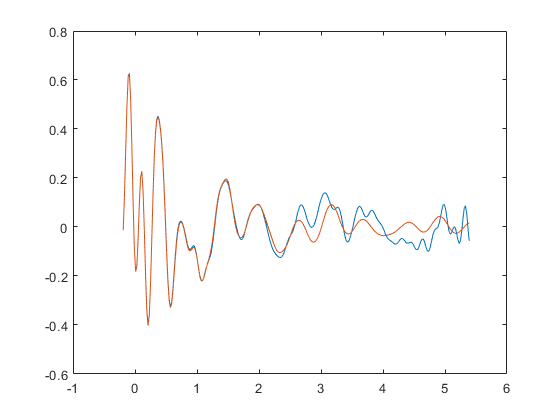

%lsqnonlin
amp_fit1=0;
freq1=0;
tau1=0;
phase1=0;
for i=1:num_freq
    
    amp_fit1(i)=param((4*i)-3);
    freq1(i)=param((4*i)-2);
    tau1(i)=param((4*i)-1);
    phase1(i)=param((4*i));
    
end

fn=0;
Harm1(1:num_freq,1:diff1)=0;
for i=1:num_freq
    comp=param((4*i)-3).*exp(-time_WT1./param((4*i)-1)).*sin((2*pi*(param((4*i)-2)*3*10^-2).*time_WT1)+param((4*i)));
    Harm1(i,:)=comp;
    fn=fn+comp;
end

figure()
plot(time_WT1,res_fit_osc);
hold on;
plot(time_WT1,fn);
hold off;

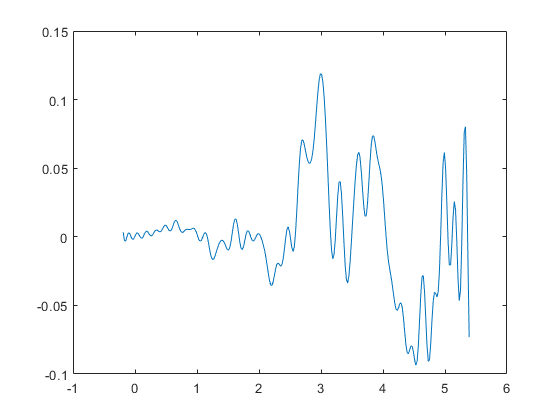

figure()
plot(time_WT1,res_fit_osc-fn);

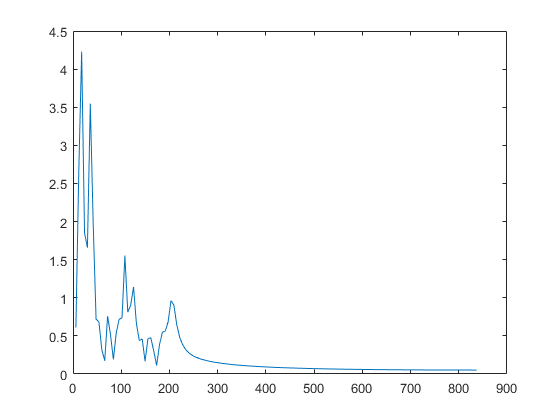

check=abs(fft(res_fit_osc-fn));
figure()
plot(omega1(1:diff1/2),check(1:diff1/2));

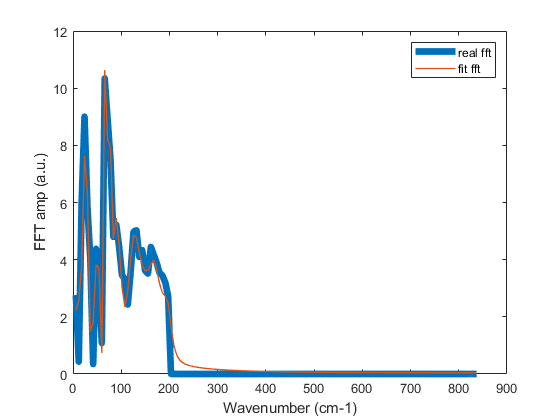


fit_fft=abs(fft(fn));
figure()
 plot(omega1(1:diff1/2),avg_fft_real(1:diff1/2),'-','linewidth', 5,'DisplayName','real fft');
 hold on;
 plot(omega1(1:diff1/2),fit_fft(1:diff1/2),'-','linewidth', 1,'DisplayName','fit fft');
 hold off;
    xlabel('Wavenumber (cm-1)');ylabel('FFT amp (a.u.)');
    legend ('show');

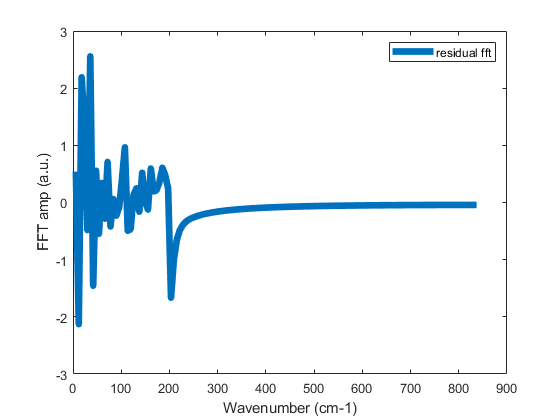

  
    figure()
 plot(omega1(1:diff1/2),avg_fft_real(1:diff1/2)-fit_fft(1:diff1/2),'-','linewidth', 5,'DisplayName','residual fft');
     xlabel('Wavenumber (cm-1)');ylabel('FFT amp (a.u.)');
    legend ('show');

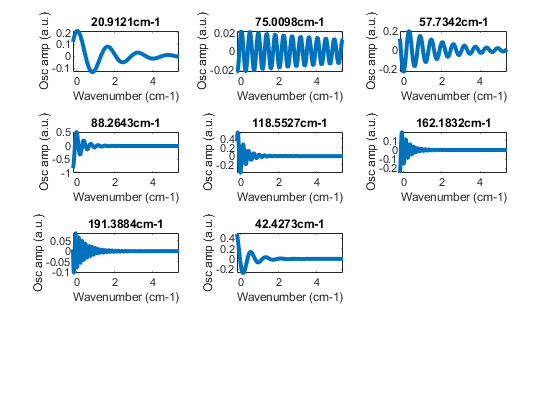

    
figure()
tiledlayout(4,3);
for ii=1:num_freq
    nexttile
    plot(time_WT1,Harm1(ii,:),'-','linewidth', 3);
    xlabel('Wavenumber (cm-1)');ylabel('Osc amp (a.u.)');
title([num2str(freq1(ii)) 'cm-1']);
end

     pcent_amp1=0;
     pcent_amp1=(amp_fit1./sum(amp_fit1))*100

pcent_amp1 =    11.1769    1.1238   11.8186   26.1081   19.6492    7.9483    4.1134   18.0616


    freq1

freq1 =    20.9121   75.0098   57.7342   88.2643  118.5527  162.1832  191.3884   42.4273


    tau1

tau1 =     1.6542   10.0000    1.9711    0.4079    0.3995    0.3932    0.5959    0.5573


    phase1

phase1 =     1.2688    0.9358    4.7250    1.5219    4.8456    4.3605    3.6403    3.3937


%     pcent_amp_mod=(amp_fit(1:num_freq-1)./sum(amp_fit(1:num_freq-1)))*100
%     freq1(1:num_freq-1)
    subtract1=0;
nb_length=100;
 
 centre_freq=12;

     wav_res=fn;
     
     figure()
plot(time_WT1,res_fit_osc);

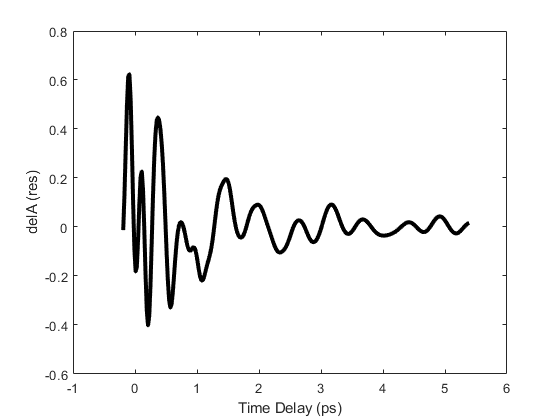

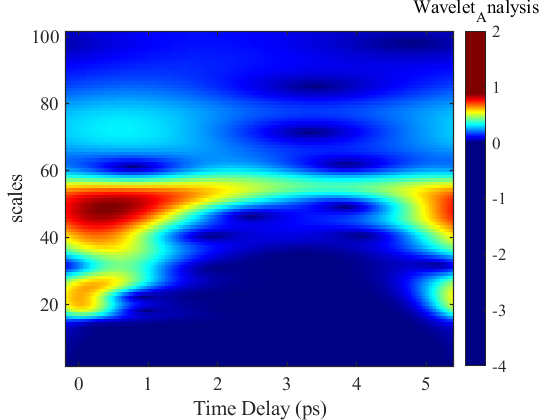

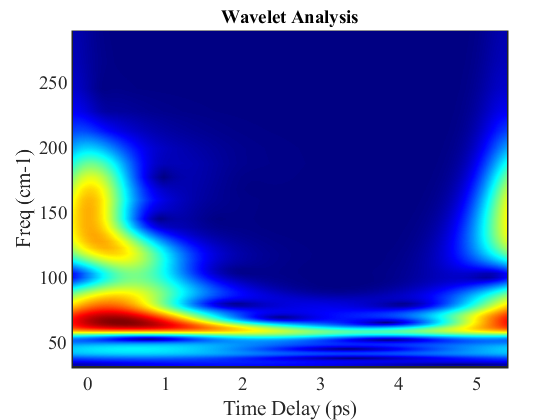


 wav_analysis=Wavelet_Analysis1(wav_res,time_WT1,dt,nb_length,subtract1,centre_freq);

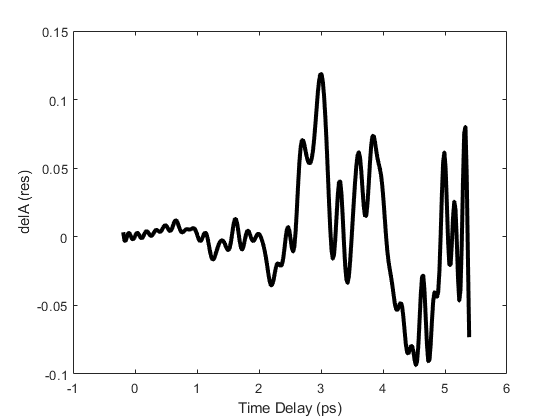

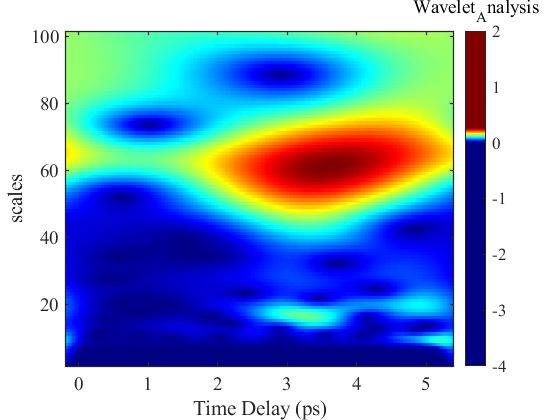

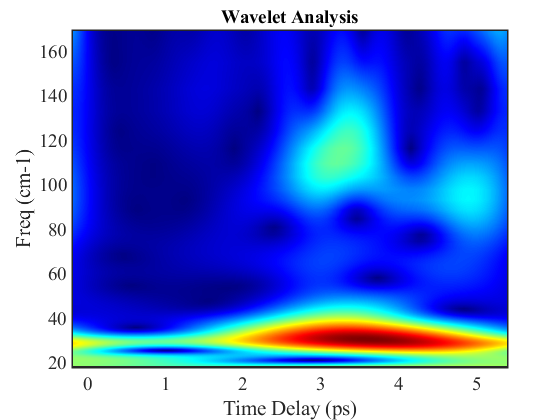

subtract1=0;
nb_length=100;
 
 centre_freq=7;

     wav_res=res_fit_osc-fn;
 wav_analysis=Wavelet_Analysis1(wav_res,time_WT1,dt,nb_length,subtract1,centre_freq);

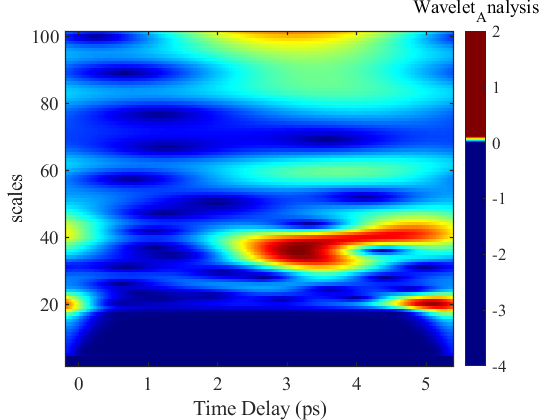

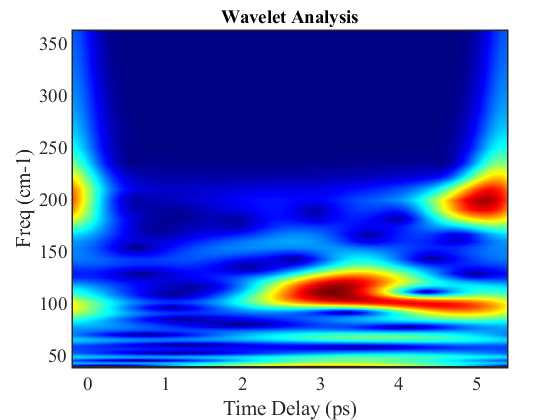


 centre_freq=15;

     wav_res=res_fit_osc-fn;
 wav_analysis=Wavelet_Analysis1(wav_res,time_WT1,dt,nb_length,subtract1,centre_freq);